# **LAB3: 3.8 和 3.10**

朱泺源 12511622    罗玛 12510925

**实验目标概括：**

计算离散时间系统的频率响应，观察滤波器对周期信号的影响；比较直接计算 DTFS 和 FFT 的运算量，并使用周期卷积性质计算周期卷积。

**具体实验内容：**

3.8：计算两个一阶递归系统的频率响应，重建周期输入，比较两组输出波形和 DTFS 系数。

3.10：比较直接 DTFS 和 FFT；分别用直接法和 FFT 计算 N=40、80 的周期卷积。

**(1)题目解析**

**3.8 一阶递归离散时间滤波器**

系统 1：y[n]-0.8y[n-1]=x[n]；系统 2：y[n]+0.8y[n-1]=x[n]。系统函数分别为 H1=1/(1-0.8e^(-jω))，H2=1/(1+0.8e^(-jω))。

输入周期 N=20，a[k]=3/4 (k=±1)，a[k]=-1/2 (k=±9)，其余为 0。按 DTFS 的周期性，k=-1 和 k=-9 分别对应数组中的 k=19 和 k=11。

分析公式为 a=fft(x)/N，综合公式为 x=N*ifft(a)。先从 n=-20 输入一个周期，减小 n=0 处的初始暂态。

**3.10 计算离散时间傅里叶级数**

(a) 单个系数需要 N+1 次复数乘法和 N-1 次复数加法；N 个系数合计 N(N+1) 次乘法、N(N-1) 次加法，共 2N² 次，运算量为 O(N²)。

(b)(c) 使用 dtfs(x,0) 和 fft(x)/N 计算系数，并比较 O(N²) 和 O(N log N) 的增长趋势。

(d) 由 h[n+N-r]=h[n-r] 可知 y[n+N]=y[n]，所以 N 是输出周期，基波周期可以是 N 的因数。本题给定的指数序列，其周期卷积的基波周期为 N。

(e)-(i) 按教材提示用 conv([x x],h) 计算线性卷积，并取第 N+1 到 2N 个样本得到周期卷积。FFT 方法计算 ax=fft(x)/N 和 ah=fft(h)/N，令 ay=N*ax.*ah，最后 y=N*ifft(ay)。

**(2)程序代码**

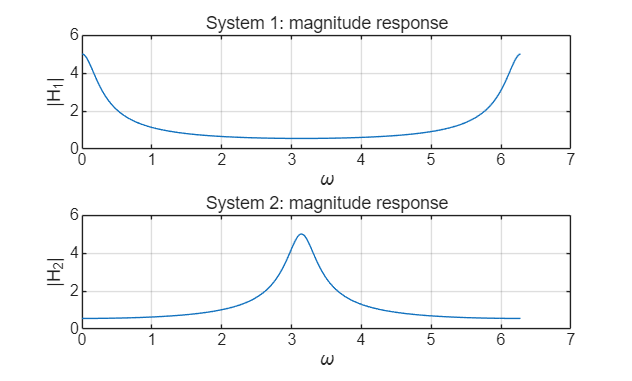

%% 3.8(a)(b) 系数向量和频率响应
a1 = [1 -0.8]; b1 = 1;
a2 = [1  0.8]; b2 = 1;
[H1,w] = freqz(b1,a1,1024,'whole');
[H2,~] = freqz(b2,a2,1024,'whole');
figure;
subplot(2,1,1); plot(w,abs(H1)); grid on;
title('System 1: magnitude response'); xlabel('\omega'); ylabel('|H_1|');
subplot(2,1,2); plot(w,abs(H2)); grid on;
title('System 2: magnitude response'); xlabel('\omega'); ylabel('|H_2|');

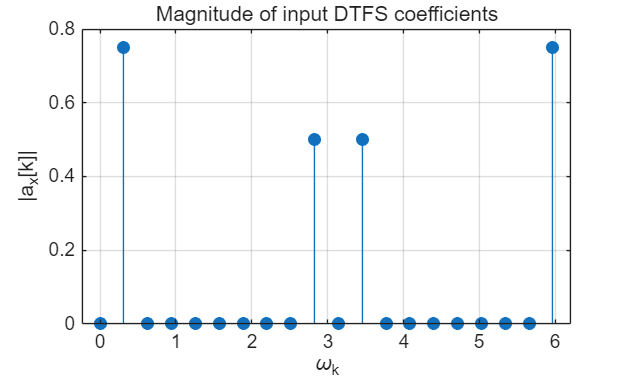

%% 3.8(c) 输入信号的 DTFS 系数
N = 20; k = 0:N-1; wk = 2*pi*k/N;
ax = zeros(1,N);
ax([2 20]) = 3/4;       % k = 1, 19
ax([10 12]) = -1/2;     % k = 9, 11
figure; stem(wk,abs(ax),'filled'); grid on;
title('Magnitude of input DTFS coefficients');
xlabel('\omega_k'); ylabel('|a_x[k]|');

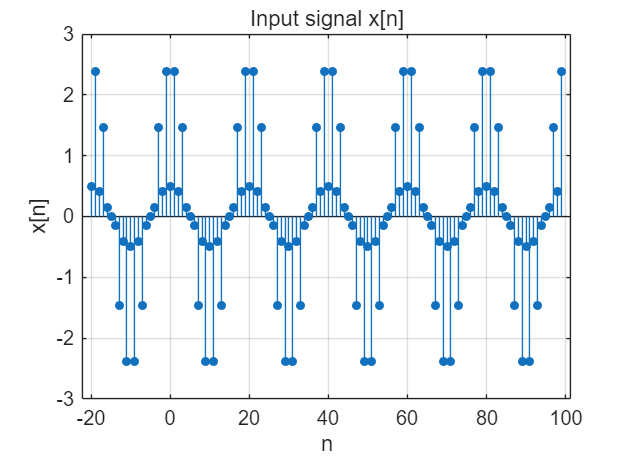

%% 3.8(d) 重建信号并扩展为六个周期
x20 = real(N*ifft(ax));
n = -20:99; x = [x20 x20 x20 x20 x20 x20];
figure('Position',[100 100 900 650]); stem(n,x,'filled','MarkerSize',4); grid on;
title('Input signal x[n]'); xlabel('n'); ylabel('x[n]');

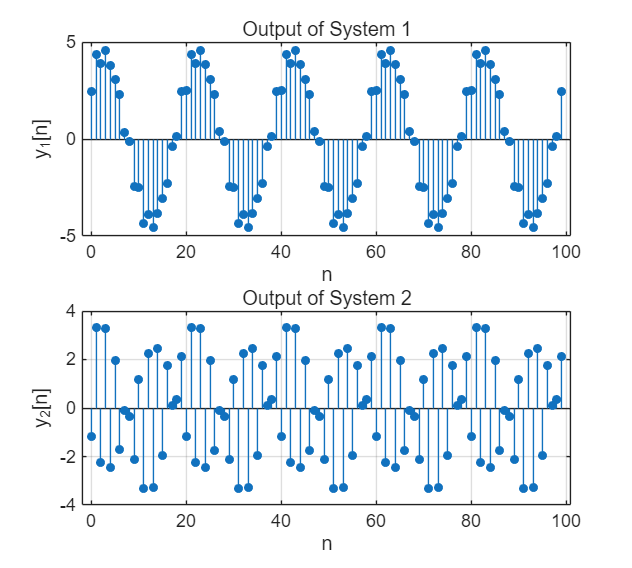

%% 3.8(e) 计算两个系统的输出
y1 = filter(b1,a1,x); y2 = filter(b2,a2,x);
ny = 0:99; y1_plot = y1(21:end); y2_plot = y2(21:end);
figure('Position',[100 100 1000 900]);
subplot(2,1,1); stem(ny,y1_plot,'filled','MarkerSize',4); grid on;
title('Output of System 1'); xlabel('n'); ylabel('y_1[n]');
subplot(2,1,2); stem(ny,y2_plot,'filled','MarkerSize',4); grid on;
title('Output of System 2'); xlabel('n'); ylabel('y_2[n]');

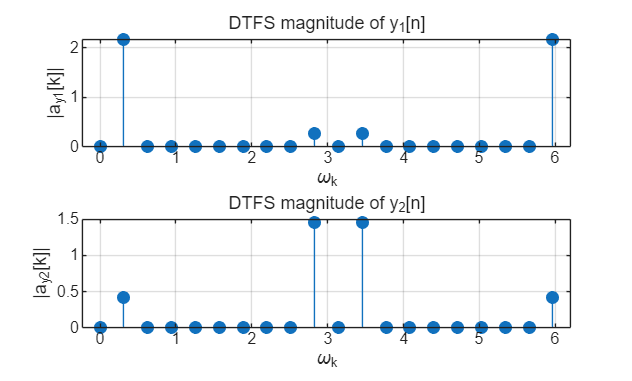

%% 3.8(f) 计算输出的 DTFS 系数
y1_20 = y1_plot(1:20); y2_20 = y2_plot(1:20);
ay1 = fft(y1_20)/N; ay2 = fft(y2_20)/N;
figure;
subplot(2,1,1); stem(wk,abs(ay1),'filled'); grid on;
title('DTFS magnitude of y_1[n]'); xlabel('\omega_k'); ylabel('|a_{y1}[k]|');
subplot(2,1,2); stem(wk,abs(ay2),'filled'); grid on;
title('DTFS magnitude of y_2[n]'); xlabel('\omega_k'); ylabel('|a_{y2}[k]|');

disp('                   k=1          k=9');

                   k=1          k=9


disp('System 1:'); disp(abs(ay1([2 10])));

System 1:
    2.1772    0.2818



disp('System 2:'); disp(abs(ay2([2 10])));

System 2:
    0.4223    1.4509



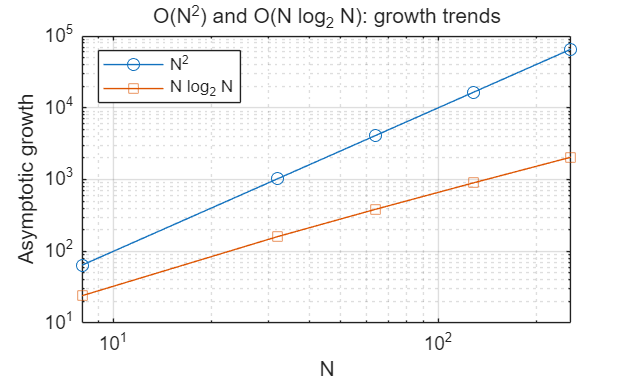

%% 3.10(b) 直接计算 DTFS：教材 3.5 要求的函数
function a = dtfs(x,n_init)
N = length(x);
a = zeros(1,N);
for k = 0:N-1
    s = 0;
    for m = 0:N-1
        n = n_init+m;
        s = s + x(m+1)*exp(-1j*2*pi*k*n/N);
    end
    a(k+1) = s/N;
end
end
%% 3.10(b)(c) 直接 DTFS 与 FFT
N_values = [8 32 64 128 256];
for i = 1:length(N_values)
    N = N_values(i);
    x = (0.9).^(0:N-1);
    X = dtfs(x,0);
    X_fft = fft(x)/N;
end

% 比较两种算法的理论增长趋势
figure;
loglog(N_values,N_values.^2,'o-',N_values,N_values.*log2(N_values),'s-');
xlabel('N'); ylabel('Asymptotic growth');
title('O(N^2) and O(N log_2 N): growth trends');
legend('N^2','N log_2 N','Location','northwest');
grid on;

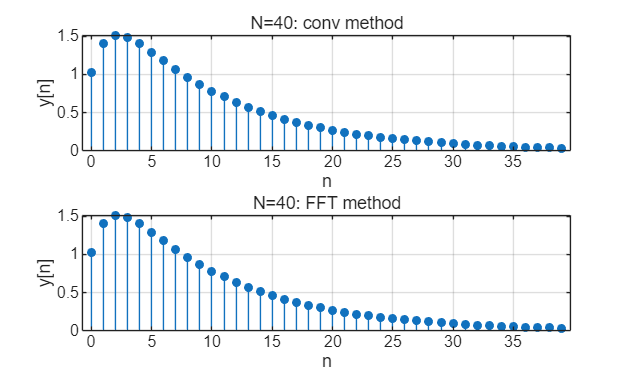

%% 3.10(e)(g) N=40 的周期卷积
N = 40; n = 0:N-1; x = (0.9).^n; h = (0.5).^n;
v = conv([x x],h);
yc40 = v(N+1:2*N);
ax = fft(x)/N; ah = fft(h)/N;
ay = N*ax.*ah;
yf40 = real(N*ifft(ay));
figure;
subplot(2,1,1); stem(n,yc40,'filled','MarkerSize',4); grid on;
title('N=40: conv method'); xlabel('n'); ylabel('y[n]');
subplot(2,1,2); stem(n,yf40,'filled','MarkerSize',4); grid on;
title('N=40: FFT method'); xlabel('n'); ylabel('y[n]');

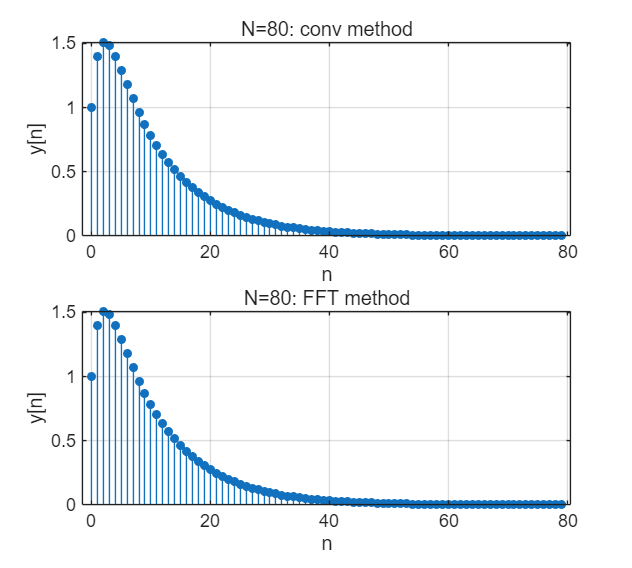

%% 3.10(f)(h) N=80 的周期卷积
N = 80; n = 0:N-1; x = (0.9).^n; h = (0.5).^n;
v = conv([x x],h);
yc80 = v(N+1:2*N);
ax = fft(x)/N; ah = fft(h)/N;
ay = N*ax.*ah;
yf80 = real(N*ifft(ay));
figure('Position',[100 100 1000 900]);
subplot(2,1,1); stem(n,yc80,'filled','MarkerSize',4); grid on;
title('N=80: conv method'); xlabel('n'); ylabel('y[n]');
subplot(2,1,2); stem(n,yf80,'filled','MarkerSize',4); grid on;
title('N=80: FFT method'); xlabel('n'); ylabel('y[n]');

**(3)结果图**

运行程序后，各题的结果图显示在对应代码下方。

**(4)结果分析**

**3.8：**

系统 1 是低通滤波器，系统 2 是高通滤波器。对低频 ω=π/10，两者增益分别约为 2.9073 和 0.5624；对高频 ω=9π/10，增益分别约为 0.5624 和 2.9073。

因此 y1 的低频成分更明显，波形较平缓；y2 的高频成分更明显，波形振荡较快。取 n=0:19 得到的 |ay1| 在 k=1、9 处约为 2.1772、0.2818；|ay2| 约为 0.4223、1.4509。少量差异来自零初始条件的残余暂态。

**3.10：**

直接计算 DTFS 的复杂度是 O(N²)，FFT 是 O(N log N)。N 增大时，FFT 的理论运算量增长较慢。

N=40 和 N=80 时，直接周期卷积和 FFT 结果一致，二者的最大差异仅为浮点误差。第一个样本分别约为 1.0184761 和 1.0002731。

直接计算的复杂度为 O(N²)，FFT 的复杂度为 O(N log N)，所以 N 较大时通常选择 FFT 方法。这里比较的是理论增长趋势，未计算实际运算次数比。

**经验总结：**

@朱泺源> 使用 fft 和 ifft 计算 DTFS 时，需要注意周期 N 的比例；观察滤波结果时也要考虑初始暂态。

@罗玛> 计算周期卷积时，可以按教材提示使用 conv([x x],h)，再用 FFT 的结果进行对比。

**自我评价：**

**@朱泺源 10**

**@罗玛 10**